# Simulation of PELDOR time traces

# assuming a Gaussian distributed distance

#### Tutorial Program from Thomas Prisner 17.6.2020

The purpose of this program is to learn how 

1) the mean distance Rmax

2) the width of the gaussian distributed distance DeltaR

3) the labeling efficiency FLabel

effect the PELDOR time trace

Here we assume a single Gaussian distributed distance between both spin labels: 


$$P\left(R\right)=\exp \left(-\frac{{\left(R-R_{\max } \right)}^2 }{2{\cdot \textrm{deltaR}}^2 }\right)$$


## Parameters which have to be adjusted !

Cm=400e-6;          % Local Spin concentration in Mol/dm^3 for intermolecular background (in optimal case molecule concentration *2)
fLabel=0.5;           % Labeling efficiency (might be smaller than 1 by reduction, insufficient chemical reaction etc)
Rmax=2.38;             % maximum of Gaussian distance distribution P(R)
deltaR=0.08;           % Width of Gaussian distance distribution P(R)

#### Calculate the Gaussian Distance distribution

% define the distance vector for P(R) distribution
lbR=1;            % lower boundaries for R in nm
ubR=6;            % upper boundaries for R in nm
Rstep=0.05;      % resolution in R in nm         
R=lbR:Rstep:ubR; % R vector
nR=length(R);     % dimension of R vector
PR=exp(-(R-Rmax).^2/(2*deltaR^2));        % Create Gaussian distance distribution function P(R) 
PR=PR/sum(PR);                          % normalize to 1 integral intensity
PR=PR';                                 % change to column vector

Show the distance distribution

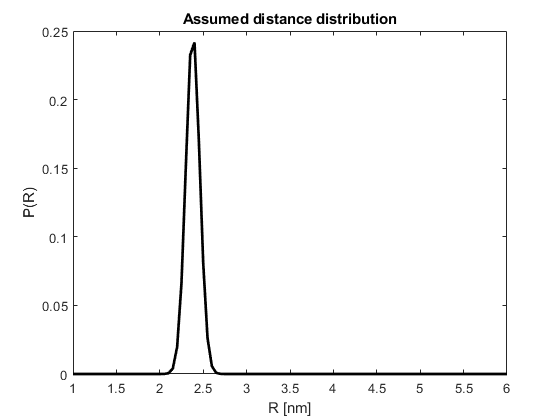

plot(R,PR,'k','LineWidth',2)
xlabel('R [nm]')
ylabel('P(R)')
title('Assumed distance distribution')

#### Constants used for the simulation

gammae=28;  % Gyromagnetic ratio for Electron spin [MHz / mT]
NL=6.6e23;  % Avogadro Number
h=6.626e-34; % Planck Constant [J/s]
hq=h/(2*pi); % reduced Planck Constant h/2Pi
u0=4*pi*10^(-7); % Vaccum permeabiltiy
uB=9.274e-24;  % Bohr Magneton
Dipconst=52.18;  % dipolar constant [MHz/nm^3]

#### Experimental parameters

load DataPELDORSim;                % Loads experimental data: time vector t [us] and EchoSignal vector Signalexp (normalized to 1 for t=0)
nt=length(t);                       % Length of the time and Signalexp vectors 
band='Q';           % define the spectrometer used ('X', 'Q', 'G', 'J' band)
tpPump=0.032;       % MW pump pulse length in µs
tpProbe=0.032;      % MW probe pulse (pi) length in µs
vOffPump=0;         % shift of pump frequency against the maximum of the spectra in MHz 
vOffProbe=-70;      % Offset frequency in MHz between Pump and Probe pulses in MHz

Show the experimental time trace

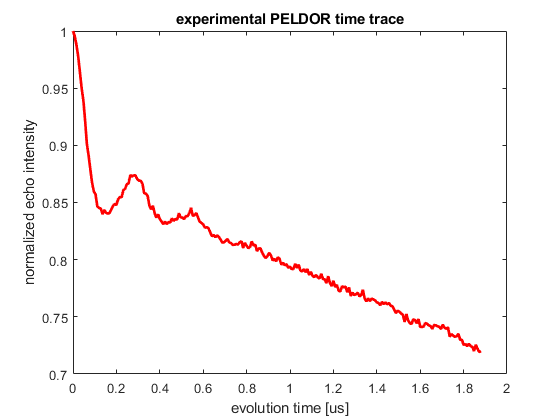

plot(t,Signalexp,'r','LineWidth',2);
xlabel('evolution time [us]')
ylabel('normalized echo intensity')
title('experimental PELDOR time trace')

#### Sample parameters

Nitroxide.g = [2.008,2.006,2.003];                   % g tensor for nitroxide spin label
g=mean(Nitroxide.g);                                 % mean g value for prefactor
Nitroxide.Nucs = '14N';                              % Nitrogen nuclear spin 
Nitroxide.A = [20,20,90];                            % Nitrogen hyperfine coupling [MHz]                         
Nitroxide.lw=1;                                      % Unresolved couplings lineWidth [mT]

####  Calculate Spectra and Show excited spins by probe and pump pulses

% Calculate the excitation frequency from chosen spectrometer 
% (exact values are not important because of internal recalibration on spectra) 
switch band
    case 'X'
        Experiment.mwFreq = 9.5;   % GHz X-band
    case 'Q'
        Experiment.mwFreq = 34;   % GHz Q-band
    case 'G'
        Experiment.mwFreq = 180;   % GHz G-band
    case 'J'
        Experiment.mwFreq=260;  % GHz J band    
end
Experiment.Harmonic = 0;                                    % Pure Absorption Spectra (not first derivative)
[B0,Spectra] = pepper(Nitroxide,Experiment);                % B0: magnetic field axis [mT], Spectra: Simulated Spectra
Spectra=Spectra/sum(Spectra);                               % Spectra normalized to integral intensity of 1

v0=gammae*B0;                                               % frequency axis generated from B0 Vector [MHz]

indexmax=find(Spectra==max(Spectra));                       % find the maxiumum of the Spectra (for positioning of vMW(Pump)
v0Max=v0(indexmax);                                         % frequency of Spectra maxima
vPump=v0-v0Max+vOffPump;                                    % pump pulse offset frequency axis
vProbe=vPump+vOffProbe;                                     % probe pulse offset frequency axis

% calculate the pulse pump and probe excitation profiles (for rectangular pulses)
% Using Bloch-Vector rotation 
M0 = [0;0;1];                                               % equilibrium magnetization vector along z axis
offPhasePump = 2*pi*tpPump*vPump;                           % Phase offset for Pump pulse 
offPhaseProbe=2*pi*tpProbe*vProbe;                          % Phase offset for Probe pulses
flipAngle = pi;                                             % nominal on-resonance flip angle for pump pulse (and probe pi/pulse) 
% Comute deltaMz for pump and probe pulses over all possible spectral  positions
MzPump=zeros(size(Spectra));                                % Starting values
MzProbe = zeros(size(Spectra));
% loop over all spectral positions
for k = 1:length(v0)
            MPump = expm([0 offPhasePump(k) 0; -offPhasePump(k) 0 -flipAngle; 0 flipAngle 0])*M0;     % Bloch-Equation
            MzPump(k) = MPump(3);           % only z-component
            MProbe = expm([0 offPhaseProbe(k) 0; -offPhaseProbe(k) 0 -flipAngle; 0 flipAngle 0])*M0;  % Bloch-Equation
            MzProbe(k) = MProbe(3);         % only z-component 
end
IexPump=-(MzPump-1)/2;          % normalized pump profile as function of Offset        
IexProbe=-(MzProbe-1)/2;        % normalized probe profile as function of Offset
    
lambda=sum(IexPump.*Spectra);                           % excitation efficiency of pump pulse
IntSignalwo=sum(IexProbe.*Spectra);                     % normalized Signal intensity without pump pulse
PumpSignalReduction=sum(IexProbe.*IexPump.*Spectra);    % detection Signal loss with pump pulse included
IntSignalw=IntSignalwo-PumpSignalReduction;             % Intensity of Signal with Pump Pulse
PumpReduction=(IntSignalwo-IntSignalw)/IntSignalwo;     % Reduction factor of Signal intensity by Pump Pulse


Show the spectra with pump and probe pulses (in frequency units)

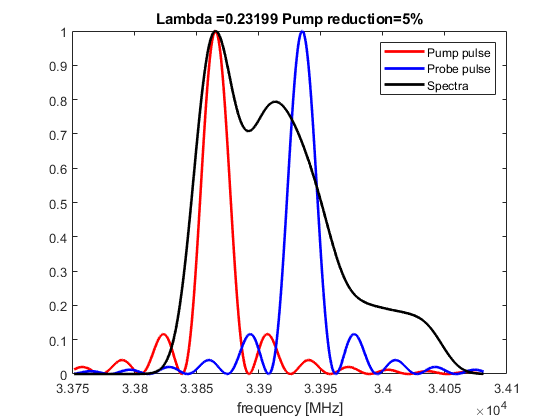

plot(v0,IexPump,'r',v0,IexProbe,'b',v0,Spectra/max(Spectra),'k','LineWidth',2);
xlabel('frequency [MHz]')
title(['Lambda =',num2str(lambda),' Pump reduction=',num2str(round(PumpReduction*100)),'%'])
legend('Pump pulse','Probe pulse','Spectra')

#### Calcuation of intermolecular PELDOR Signal time trace by matrix inversion

The Signal S(t) can be obtained from P(R) by a simple Matrix multiplication


$$\overrightarrow{S\left(t\right)} =\tilde{A} \cdot \overrightarrow{P\left(R\right)}$$


with $\tilde{A}$ beeing the integral kernel function for dipol-dipol interaction 


$$x=\cos \left(\theta \right)$$
   
$$x\in \left\lbrace 0\ldotp \ldotp 1\right\rbrace$$



$$Y=\cos \left(u\right)$$



$$M=\int Y\;\textrm{dx}$$


with $\tilde{u} =2\cdot \pi \cdot \frac{\textrm{Dipconst}\cdot \left(1-3x^2 \right)}{{\overrightarrow{R} }^3 }\ast \overrightarrow{t}$

A=Amatrix(Dipconst,nt,nR,t,R);          % call of function to create A matrix
VS=A*PR;                                % create time vector from distance distribution
VS=VS/max(VS);                          % normalize to 1
lambdaf=lambda*fLabel;                  % reduced lambda value by labeling efficiency
Amplitude=1-lambdaf;                     % modulation depth 
Form=Amplitude+lambdaf*VS;               % Form factor

####  Calculate the signal decay by intermolecular dipol-dipol interactions 

% Calculate the parameter for intermolecular decay
CC=10^3*NL;                                                 % Spin concentration prefactor for change from Mol/l to Spins/m^3
Kinter=(2*pi*g^2*uB^2*u0*lambda*CC)/(9*sqrt(3)*hq)*1e-6;    % intermolecular decay constant in MHz
Signalinter=exp(-Kinter*Cm*t);
Signalback=Signalinter*Amplitude;        % rescaled intermolecular background function  

#### Calculate the overall PELDOR time trace 

#### 
$$S\left(t\right)=\textrm{Form}\cdot {\textrm{Signal}}_{\textrm{inter}}$$
 

Signalfit=Form.*Signalinter;             % Total PELDOR time trace including intermolecular decay

Show the resulting fit and the residuum between fit and experimental data

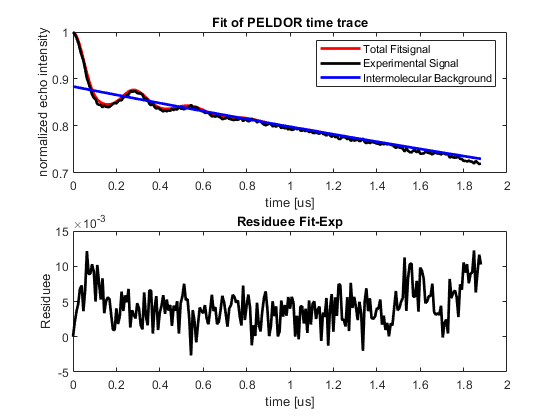

subplot(211)
plot(t,Signalfit,'r',t,Signalexp,'k',t,Signalback,'b','LineWidth',2);
xlabel('time [us]')
ylabel('normalized echo intensity')
title('Fit of PELDOR time trace')
legend('Total Fitsignal','Experimental Signal','Intermolecular Background')
subplot(212)
plot(t,Signalfit-Signalexp,'k','LineWidth',2);
xlabel('time [us]')
ylabel('Residuee')
title('Residuee Fit-Exp')

#### Functions used above:

function f=Amatrix(Dipconst,nt,nR,t,R)
xw=0:0.001:1;                   % cos(theta) vector
A=zeros(nt,nR);
for k1=1:nt
    for k2=1:nR
        arg=(1-3*xw.^2)*2*pi*Dipconst*t(k1)/R(k2)^3;
        Y=cos(arg);
        A(k1,k2)=trapz(xw,Y);
    end
end
f=A;
end